k = 4.756;
t = 1.231;

s = tf('s');

P(1,1,1) = 4.756/(1.231*s+1); %nominal plant, low inertia
P(1,1,2) = 2.533/(0.3968*s+1); %low inertia + magnetic break
P(1,1,3) = 4.759/(6.8823*s+1); %high inertia

[Gm1,Pm1,Wcg1,Wcp1] = margin(P(1,1,1));
[Gm2,Pm2,Wcg2,Wcp2] = margin(P(1,1,2));
[Gm3,Pm3,Wcg3,Wcp3] = margin(P(1,1,3));
% bode(P)
Wcp1

Wcp1 = 3.7772

Wcp2

Wcp2 = 5.8650

Wcp3

Wcp3 = 0.6760

w = [Wcp3,Wcp1,Wcp2,10];
ws = 10.^([3,3,3,3]/20);

w1 = [Wcp3,Wcp1,Wcp2];
% plottmpl(w1,P)

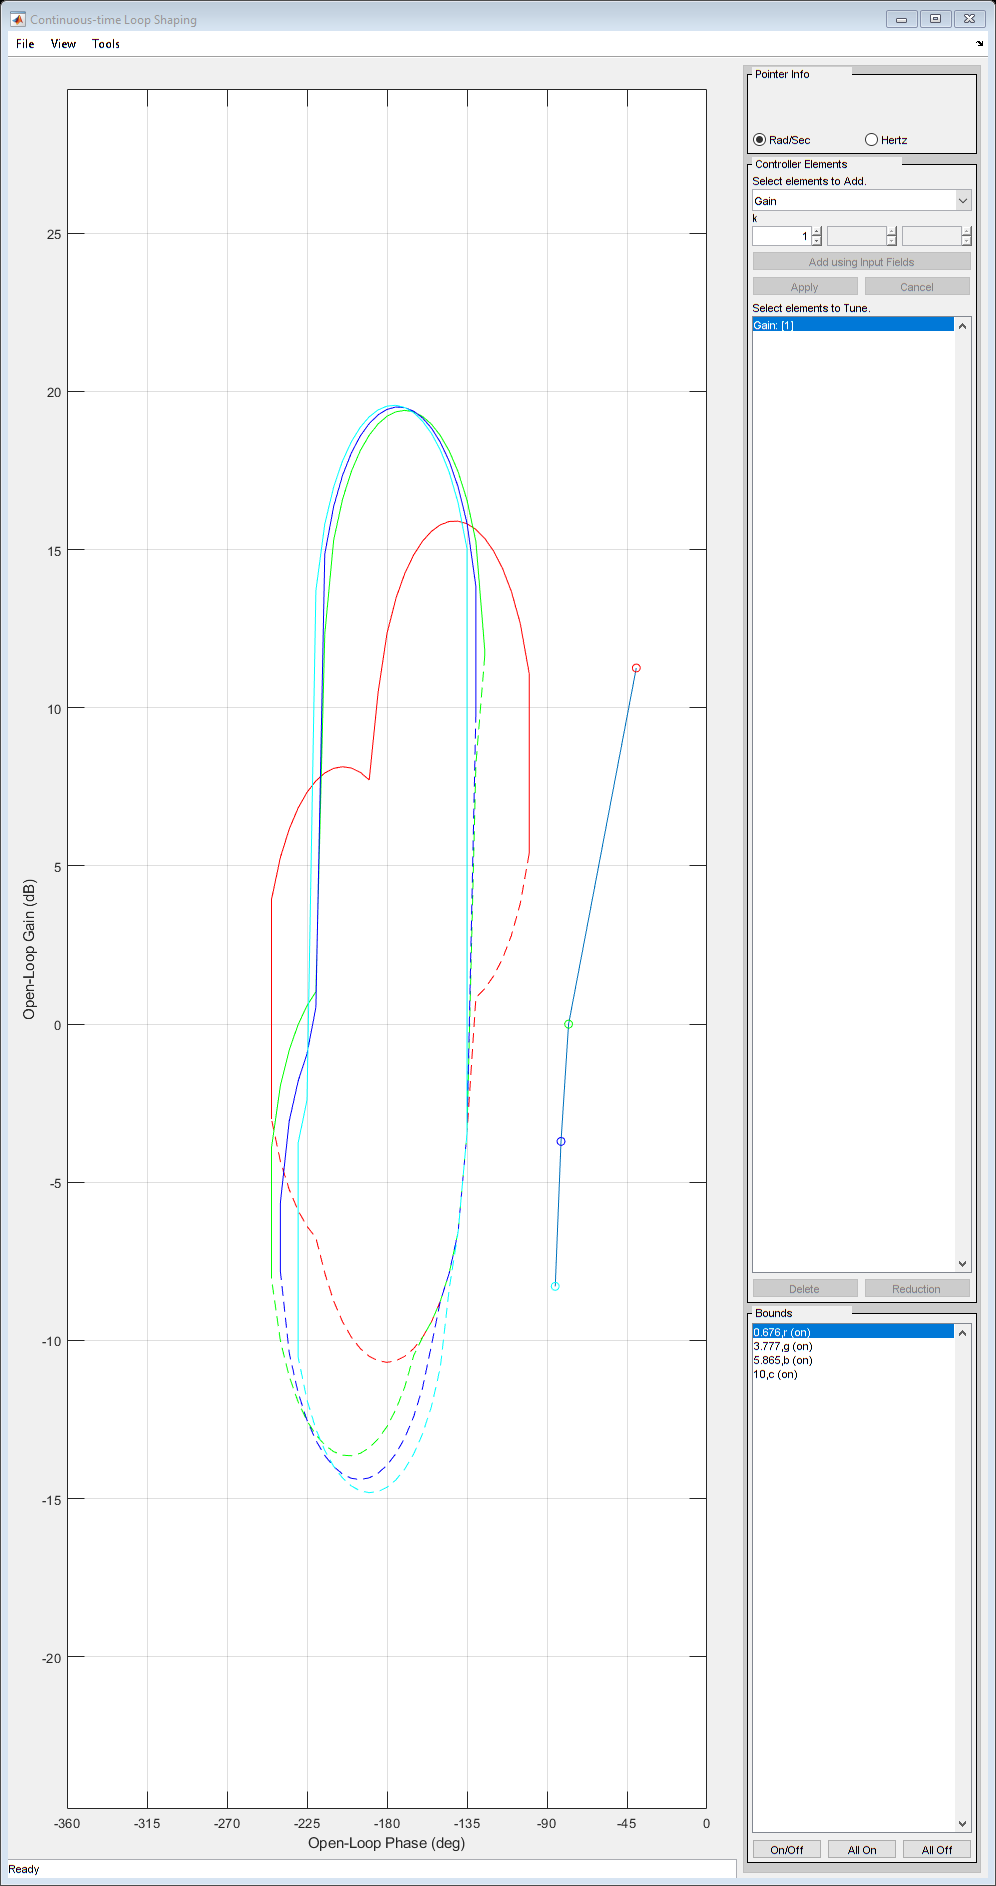

% axis([-100 0 -30 15])
bnd=sisobnds(2,w,ws,P); % Calculate the nominal bounds from the specs
% plotbnds(bnd);           % Plot

lpshape(w,bnd,P(1,1,1)) % QFT design


% sisotool(P) % Root locus design

% pidTuner(P(1,1,1)) % PID design

% G = tf([2.002 -1.438],[1 -1],0.05)
% Gv=d2c(G, 'tustin')

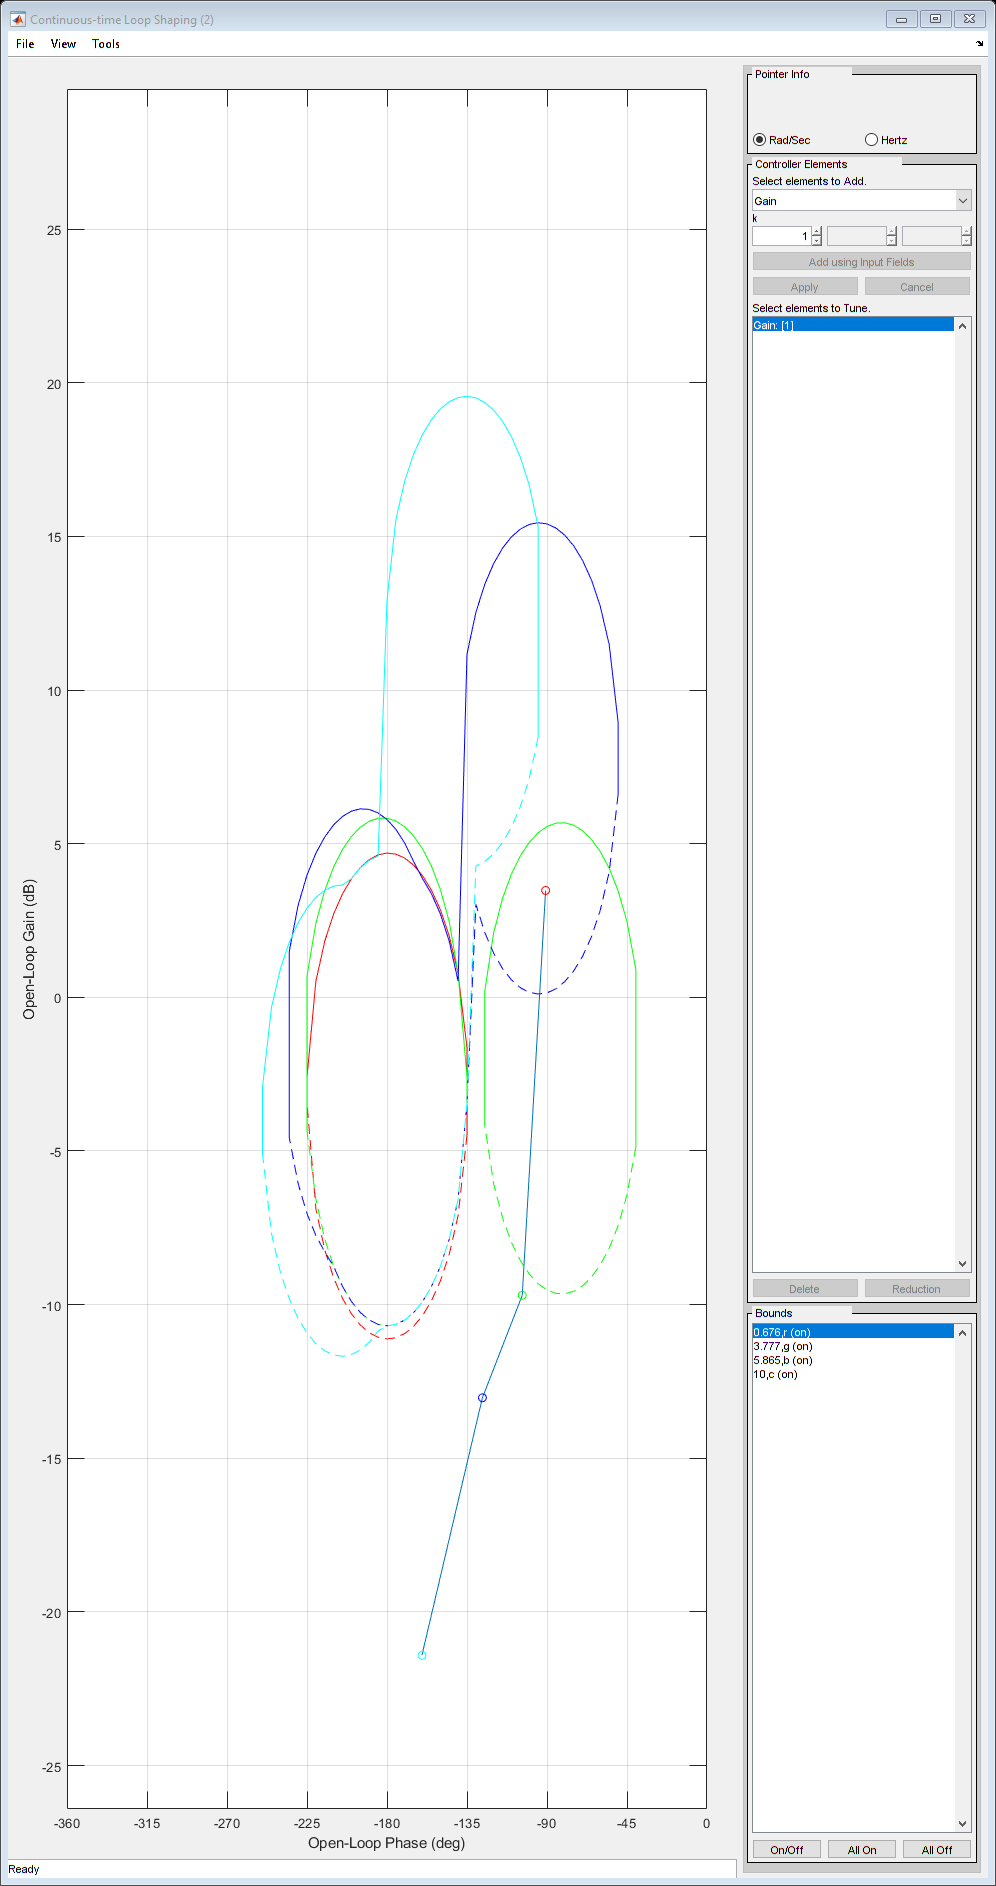

Gv = 1.72*(s+6.55814)/s;
Lv = Gv*P;
Tv = Lv/(Lv+1);
bnd=sisobnds(2,w,ws,Tv/s); % Calculate the nominal bounds from the specs
% plottmpl([Wcp1, Wcp2, Wcp3],Tv/s)
% plotbnds(bnd);           % Plot
% sisotool(Tv/s)
lpshape(w,bnd,Tv(1,1,1)/s) % QFT design

Gpp = 1.5;
% Gv = 1.72*(s+6.58)/s;
step1 = stepDataOptions('InputOffset', 0, 'StepAmplitude', 5);
% step(Gv*Tv(1,1,1,1)/(1+Gpp*Tv(1,1,1,1)), step1)
% step(Gpp*Tv(1,1,2)/(1+Gpp*Tv(1,1,2)), step1)
% step(Gpp*Tv(1,1,3)/(1+Gpp*Tv(1,1,3)), step1)
